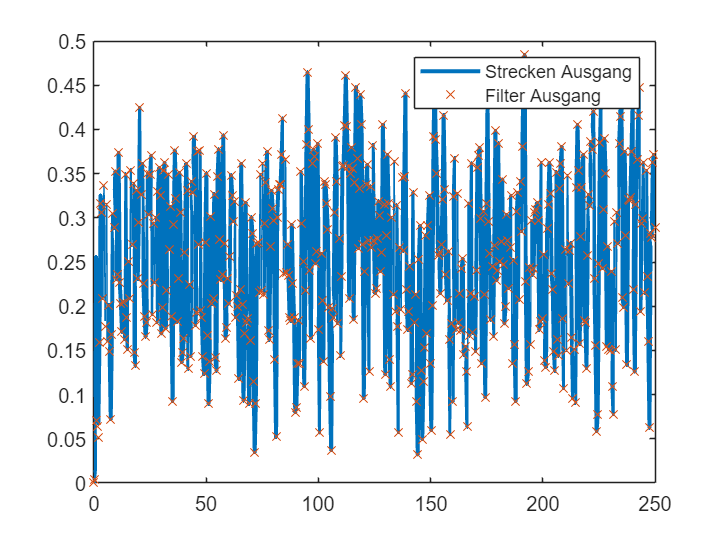

% clear all
strecke = tf(1,[1 10 20]);
time_span = 250; %time in seconds
frequency = 2; %sample frequency in Hz
samples = frequency*time_span;


time_vector = linspace(0,time_span,samples);
% input_signal = sin(time_vector);
input_signal = rand(samples,1)*10;

%Ausgangssignal simulieren
output_signal = lsim(strecke,input_signal,time_vector);

%Filterparameter
num_taps = 10; % Anzahl der Filterkoeffizienten
w = zeros(num_taps, 1); % Initialisierung mit Nullen
mu = 0.02/num_taps;

%Adaptiven Filter an jedem Zeitpunkt berechnen und sein Ausgangssignal an
%diesem Zeitpunkt
adaptive_filter_out = zeros(samples,1);
for t = 1:length(time_vector)
    w = adapt_filter_until(w, input_signal, output_signal, mu, t);
    adaptive_filter_out(t) = fir_filter(input_signal, w, t);
end
%Fehler zwischen Soll Signal und Filter Ausgang
error_out = output_signal-adaptive_filter_out;

%plotten
figure 
plot(time_vector,output_signal,'LineWidth',2);
hold on
plot(time_vector,adaptive_filter_out, 'x');
legend('Strecken Ausgang', 'Filter Ausgang')
hold off

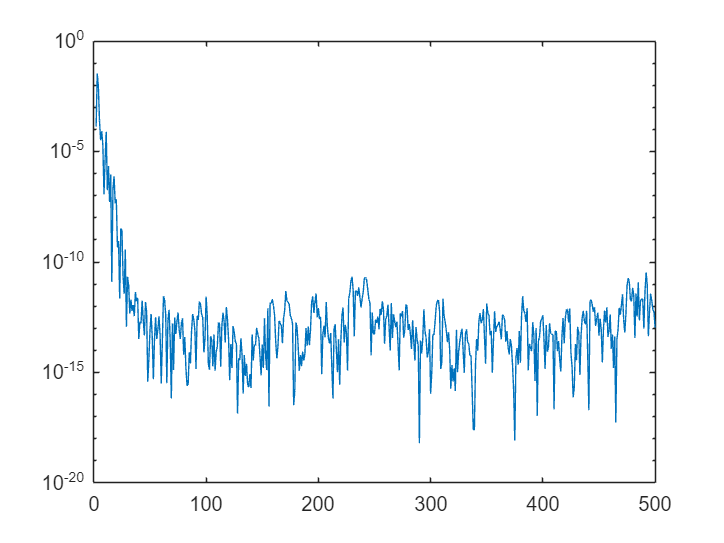

figure
semilogy(error_out.^2)

%% fir_filter function test
% c = [-0.02010411882885732
% -0.05842798004352509
% -0.061178403647821976
% -0.010939393385338943
% 0.05125096443534972
% 0.033220867678947885
% -0.05655276971833928
% -0.08565500737264514
% 0.0633795996605449
% 0.31085440365663597
% 0.4344309124179415
% 0.31085440365663597
% 0.0633795996605449
% -0.08565500737264514
% -0.05655276971833928
% 0.033220867678947885
% 0.05125096443534972
% -0.010939393385338943
% -0.061178403647821976
% -0.05842798004352509
% -0.02010411882885732
% ]
% 
% imp = zeros(length(c),1);
% imp(1) = 1;
% out = zeros(length(c),1);
% for i = 1:length(c)
%     out(i) = fir_filter(imp,c,i);
% end
% plot(out)

function output = fir_filter(input,coeff,position)
%calculate the current filter output for the input[position]
N = length(coeff);
output = 0;
for i = 1:N
    if position - i + 1 > 0 
        output = output + coeff(i) * input(position - i + 1);
    end
end
end

%Perform LMS Algorithm
%input_signal needs to include the last length(w) values
function w1 = lms(w0,error,input_signal,index,mu)
    w1 = w0;
    for p = 1:length(w0)
        if index-p+1 > 0
        w1(p) = w0(p) + 2 * mu * error * input_signal(index-p+1);
        end
    end
end

%%Adapt filter over whole input and desired signal
function adaptedCoeff = adapt_filter_whole(startCoeff, inputSignal, desiredOutputSignal, mu)
    N = length(inputSignal);
    c =  startCoeff;
    for index = 1:N
        u = desiredOutputSignal(index);
        filter_out = fir_filter(inputSignal,c,index);
        e =  u - filter_out;
        c = lms(c,e,inputSignal,index,mu);
    end
    adaptedCoeff = c;
end

%%adapt filter until a position in the input and desired signal
function adaptedCoeff = adapt_filter_until(startCoeff, inputSignal, desiredOutputSignal, mu, position)

    c =  startCoeff;
    for index = 1:position
        u = desiredOutputSignal(index);
        filter_out = fir_filter(inputSignal,c,index);
        e =  u - filter_out;
        c = lms(c,e,inputSignal,index,mu);
    end
    adaptedCoeff = c;
end

